%%%% ============= Node Wise Similar Load Profile: PCA Spatial Data Reconstruction ============= %%%%

clear all
close all
clc

file='Data.xlsx';
[status,sheets] = xlsfinfo(file)

status = 'Microsoft Excel Spreadsheet'

sheets = 1×9 cell array
    {'Busdata'}    {'similar _node_LP'}    {'Node_sim_covmatrix'}    {'Error'}    {'Dissimilar_node_train'}    {'Dissimilar_node_test'}    {'INAE calculation'}    {'bus_data'}    {'branch_data'}



% =================  Bus power data of IEEE 123 bus ================= %
% data1=xlsread(file,1); % Bus power data
% bus=data1(:,1);
% phA_kw=data1(:,2);
% phA_kVAR=data1(:,3);
% phB_kw=data1(:,4);
% phB_kVAR=data1(:,5);
% phC_kw=data1(:,6);
% phC_kVAR=data1(:,7);
% T_kw=data1(:,8);
% T_kVAR=data1(:,9);
% Nbus=max(bus);

data1=xlsread(file,8); % Bus power data
bus=data1(:,1);
T_kw=data1(:,2);
T_kVAR=data1(:,3);
Nbus=max(bus)

Nbus = 128

data1

data1 =     1.0000         0         0
    2.0000         0         0
    3.0000   13.3300    6.6670
    4.0000    6.6670    3.3330
    5.0000         0         0
    6.0000   13.3300    6.6670
    7.0000    6.6670    3.3330
    8.0000   13.3300    6.6670
    9.0000    6.6670    3.3330
   10.0000         0         0



% offline similar voltage data of IEEE 123 bus system
sim_voltages = xlsread("all_bus_voltages_similar.xlsx");
sim_data = sim_voltages(2:end,2:end);
[cols,index] = sort(sim_voltages(1,2:end));
sorted_sim_voltages = sim_data(:,index)'

sorted_sim_voltages =     1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496
    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0496    1.0




% ============ Sample load profile generation: 1-min ============== %
% T=96; 
T=24*60;
% ==== Similar Load Profile ====
% L=zeros(T,1);
% for t=1:T
%     L(t,:)=(1.3-0.8)*rand+0.8;
% end
%plot(L)
% training load profile plot
load_profile = xlsread(file,2)

load_profile = 1.0e+03 *

    0.0010    0.0009    0.0010
    0.0020    0.0008    0.0012
    0.0030    0.0012    0.0009
    0.0040    0.0008    0.0009
    0.0050    0.0011    0.0011
    0.0060    0.0010    0.0011
    0.0070    0.0009    0.0009
    0.0080    0.0011    0.0011
    0.0090    0.0010    0.0012
    0.0100    0.0009    0.0012


train_profile = load_profile(:,2)

train_profile =     0.9196
    0.8146
    1.1512
    0.8038
    1.1055
    1.0040
    0.9245
    1.1262
    0.9601
    0.8518


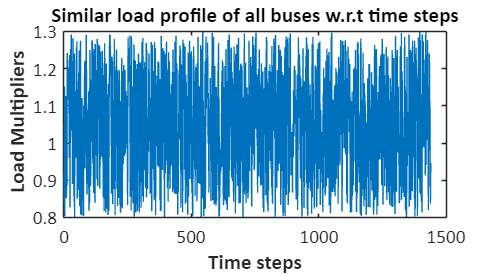

figure('Renderer', 'painters', 'Position', [10 10 900 500])
plot(train_profile)
title('Similar load profile of all buses w.r.t time steps')
xlabel('Time steps','FontWeight', 'bold')
ylabel(' Load Multipliers','FontWeight', 'bold')
set(gca,'fontsize',16,'Fontname','Calibri','GridAlpha',0.5)
saveas(gca,'similar_load_profile.svg')

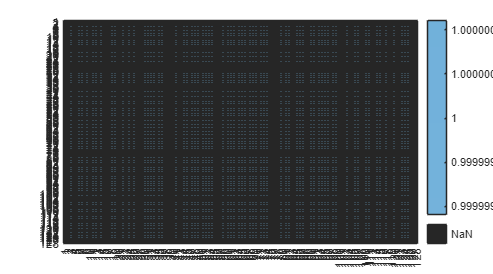

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties



% % Test load profile 15-min
data2=xlsread(file,2);
% TL=24*60/15;
% for t=1:TL
%     Lt(t,:)=(1.3-0.8)*rand+0.8;
% end


% ======== Offline calculation of PCA parameters: Bus wise ========== %
trainpu=data2(:,2);
% trainpu=data2(1:96,2); % Training with 
% plot(data2(1:96,1),trainpu)
ph=3;
P_L_demo=zeros(Nbus,T);
for n=1:Nbus
    for t=1:T
        P_L_demo(n,t)=trainpu(t,1)*T_kw(n,1);
    end
end
size_P=size(P_L_demo);


% Mean vector calculation
P_avg=zeros(Nbus,1);
for n=1:Nbus
    S=0;
    for t=1:T
        S=S+P_L_demo(n,t);
    end
    P_avg(n,1)=(1/T)*S;
end


% Correlation Matrix Calculation
Corr_P_L=zeros(Nbus,Nbus);
for m=1:Nbus
    for n=1:Nbus
        S1=0; S2=0; S3=0;
        for t=1:T
            S1=S1+(P_L_demo(m,t)-P_avg(m,1))*(P_L_demo(n,t)-P_avg(n,1));
            S2=S2+power((P_L_demo(m,t)-P_avg(m,1)),2);
            S3=S3+power((P_L_demo(n,t)-P_avg(n,1)),2);
        end
        Corr_P_L(m,n)=S1/sqrt(S2*S3);
    end
end

h=heatmap(Corr_P_L)

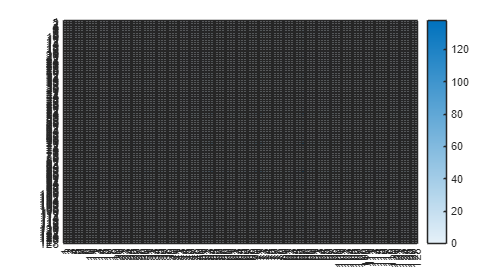


% Covariance matrix calculation
% P_L_norm=P_L_demo-P_avg;
% Cov_P_L=cov(P_L_norm)
Cov_P_L=zeros(Nbus,Nbus);
for m=1:Nbus
    for n=1:Nbus
        S=0;
        for t=1:T
            S=S+(P_L_demo(m,t)-P_avg(m,1))*(P_L_demo(n,t)-P_avg(n,1));
        end
        Cov_P_L(m,n)=(1/T)*S;
    end
end
size_cov=size(Cov_P_L);
heatmap(Cov_P_L)

Cov_P_L_pu=Cov_P_L/1000;

%heatmap(Cov_P_L)
% Eigen values (D) and vectors (V) of covariance matrix
[V,D]=eig(Cov_P_L);
% [V,D]=eig(Corr_P_L);

% Sort eigen vectors
non_sortV=V;
colSums = sum(V);
[sumsorted , sortedIndices] = sort(colSums, 'descend');  % Sort indices in descending order
sortedV = V(:, sortedIndices);  % Rearrange columns based on sorted indices


%%%%%%%%%%%%%%% Online data collection and data recovery %%%%%%%%%%%%%
itrmax=50;
%for itr=1:itrmax
    Ttest=1; % Testing time interval
    L=50; % Total number of data collecting nodes
    
    testpu=data2(:,3); % pu 15-min load at every node
    T1=96;
    % figure
    % t=1:T1;
    % plot(t,testpu(1:T1,1))
    for n=1:Nbus
        for t=1:T1
            S_L_test(n,t)=testpu(t,1)*T_kw(n,1);
        end
    end
    % figure
    % plot(S_L_test(:,1))
    
    
    % UL=sortedV(:,1:L);
    UL=sortedV(:,1:3); % only one principal component
    %S_L=zeros(Nbus,1); 
    S_L = P_avg% Original power at collected nodes

S_L =          0
         0
   13.9650
    6.9846
         0
   13.9650
    6.9846
   13.9650
    6.9846
         0


    % n_L=(randperm(Nbus, L))'; % Index of selected node 
    
    % Identify nodes having loads
    k=1;
    for n=1:Nbus
        if T_kw(n,1)~=0
            n_load(k,1)=n;
            k=k+1;
        end
    end
    
    i_L=(randperm(length(n_load), L))'; % Index of selected item from n_load
    
    % Selected Node and their actual measurement
    n_L=zeros(L,1);
    for l=1:L
        n_L(l,1)=n_load(i_L(l,1),1);
    end
    n_L

n_L =     21
    97
    96
   113
   120
    18
    11
    58
     9
    54


    n_load

n_load =      3
     4
     6
     7
     8
     9
    11
    12
    13
    14


    for l=1:L
        S_L(n_L(l,1),1,1)=testpu(Ttest,1)*T_kw(n_L(l,1),1);
    end
    S_L = S_L - P_avg;
    testpu(Ttest,1)

ans = 0.9729

    % Recovered data
    S_L_rec=P_avg+UL*UL'*S_L;
    
    % Integrated normalized absolute error (INAE)
    S_test_tot=zeros(1,T1);
    for t=1:T1
        for n=1:Nbus
            S_test_tot(1,t)=S_test_tot(1,t)+S_L_test(n,t);
        end
    end
    
    
    S_rec_tot=0;
    for n=1:Nbus
        S_rec_tot=S_rec_tot+abs(S_L_test(n,Ttest)-S_L_rec(n,1));
    end
    INAE=S_rec_tot/S_test_tot(1,Ttest)

INAE = 0.0438

    
    %Error(itr,1)=INAE*100;
%end


figure
T=1:Nbus;
p=plot(T,[S_L_test(:,Ttest),S_L_rec(:,1)],'LineWidth',1)

p =   2×1 Line array:

  Line
  Line


legend(["Original" "Reconstruct"],'Location','northwest')
p(1).Marker = 'o';
p(2).Marker = '*';
title('Reconstructed power data for similar load profile')
ylabel('Power (kW)')
xlabel('Bus number')

ax = gca

ax =   Axes (Reconstructed power data for similar load profile) with properties:

             XLim: [0 140]
             YLim: [-10 90]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


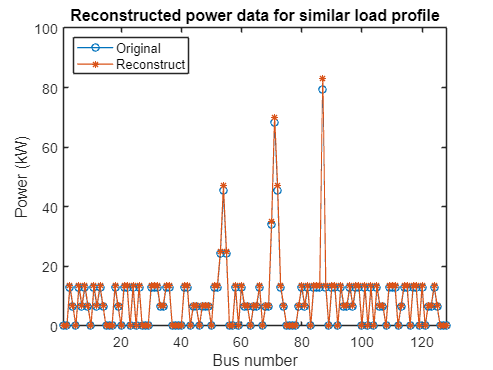

ax.FontSize = 12; 
xlim([1 128])

ax =   Axes (Reconstructed power data for dissimilar load profile) with properties:

             XLim: [1 128]
             YLim: [-10 90]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


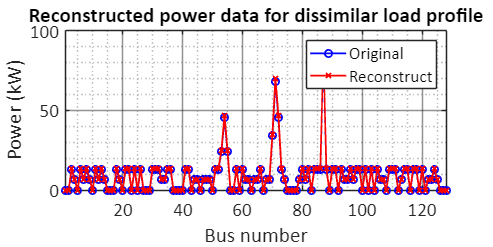

mplot(1:128,[S_L_test(:,Ttest)],1:128, [S_L_rec(:,1)])